# Actividad 3 (Análisis de transformaciones)

Elaborado por:  Marcos Allen Martínez Cortés  |  A01737939

## SISTEMA DE INTERACCIÓN (6GDL)

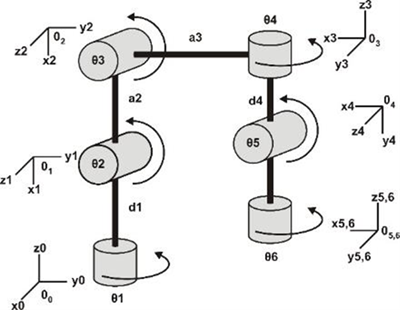

%Limpieza de pantalla
clear all
close all
clc
%SECCIÓN 1
%Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) th4(t) th5(t) th6(t) t d1 a2 a3 d4 d5
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 2
%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0 0 0 0 0];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 3
%Creamos el vector de coordenadas articulares
Q= [th1, th2, th3, th4, th5, th6];
disp('Coordenadas generalizadas');

Coordenadas generalizadas


pretty (Q);

(th1(t), th2(t), th3(t), th4(t), th5(t), th6(t))



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 4
%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
disp('Velocidades generalizadas');

Velocidades generalizadas


pretty (Qp);

/  d          d          d          d          d          d        \
| -- th1(t), -- th2(t), -- th3(t), -- th4(t), -- th5(t), -- th6(t) |
\ dt         dt         dt         dt         dt         dt        /



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 5
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 6
%Junta 1 
%Posición de la junta 1 respecto a 0
P(:,:,1)= [0; 0; d1];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,1)= [0 -sin(th1)  cos(th1);
           0  cos(th1)  sin(th1);
           -1        0        0];


%Junta 2
%Posición de la junta 2 respecto a 1
P(:,:,2)= [-a2; 0; 0];
%Matriz de rotación de la junta 2 respecto a 1
R(:,:,2)= [cos(th2) -sin(th2)  0;
           sin(th2)  cos(th2)  0;
           0         0         1];

%Junta 3
%Posición de la junta 3 respecto a 2
P(:,:,3)= [0; a3; 0];
%Matriz de rotación de la junta 3 respecto a 2
R(:,:,3)= [ sin(th3)  0  -cos(th3);
           -cos(th3)  0  -sin(th3);
           0          1         0];

%Junta 4
%Posición de la junta 4 respecto a 3
P(:,:,4)= [0; 0; -d4];
%Matriz de rotación de la junta 4 respecto a 3
R(:,:,4)= [cos(th4)   0  -sin(th4);
           sin(th4)   0   cos(th4);
           0         -1         0];

%Junta 5
%Posición de la junta 5 respecto a 4
P(:,:,5)= [0; d5; 0];
%Matriz de rotación de la junta 5 respecto a 4
R(:,:,5)= [cos(th5)  0   sin(th5);
           sin(th5)  0  -cos(th5);
           0         1         0];

%Junta 6
%Posición de la junta 6 respecto a 5
P(:,:,6)= [0; 0; 0];
%Matriz de rotación de la junta 6 respecto a 5
R(:,:,6)= [cos(th6) -sin(th6)  0;
           sin(th6)  cos(th6)  0;
           0         0         1];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 7
%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 
%Inicializamos las INVERSAS de las matrices de rotación vistas desde el marco de referencia inercial
RO_inv(:,:,GDL)= R(:,:,GDL); 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 8
for i = 1:GDL
    i_str= num2str(i);
    %Locales
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    RO_inv(:,:,i)= transpose(RO(:,:,i));
    PO(:,:,i)= T(1:3,4,i);
   %pretty(RO(:,:,i));
   % pretty(RO_inv(:,:,i));
   % pretty(PO(:,:,i));
end

Matriz de Transformación local A1


/  0, -sin(th1(t)), cos(th1(t)),  0 \
|                                   |
|  0,  cos(th1(t)), sin(th1(t)),  0 |
|                                   |
| -1,       0,           0,      d1 |
|                                   |
\  0,       0,           0,       1 /



Matriz de Transformación global T1


/  0, -sin(th1(t)), cos(th1(t)),  0 \
|                                   |
|  0,  cos(th1(t)), sin(th1(t)),  0 |
|                                   |
| -1,       0,           0,      d1 |
|                                   |
\  0,       0,           0,       1 /



Matriz de Transformación local A2


/ cos(th2(t)), -sin(th2(t)), 0, -a2 \
|                                   |
| sin(th2(t)),  cos(th2(t)), 0,  0  |
|                                   |
|      0,            0,      1,  0  |
|                                   |
\      0,            0,      0,  1  /



Matriz de Transformación global T2


/ -sin(th1(t)) sin(th2(t)), -cos(th2(t)) sin(th1(t)), cos(th1(t)),    0    \
|                                                                          |
|  cos(th1(t)) sin(th2(t)),  cos(th1(t)) cos(th2(t)), sin(th1(t)),    0    |
|                                                                          |
|       -cos(th2(t)),              sin(th2(t)),            0,      a2 + d1 |
|                                                                          |
\             0,                        0,                 0,         1    /



Matriz de Transformación local A3


/  sin(th3(t)), 0, -cos(th3(t)),  0 \
|                                   |
| -cos(th3(t)), 0, -sin(th3(t)), a3 |
|                                   |
|       0,      1,       0,       0 |
|                                   |
\       0,      0,       0,       1 /



Matriz de Transformación global T3


/  sin(th1(t)) cos(#1), cos(th1(t)),  sin(th1(t)) sin(#1), -a3 cos(th2(t)) sin(th1(t)) \
|                                                                                      |
| -cos(th1(t)) cos(#1), sin(th1(t)), -cos(th1(t)) sin(#1),  a3 cos(th1(t)) cos(th2(t)) |
|                                                                                      |
|       -sin(#1),            0,             cos(#1),         a2 + d1 + a3 sin(th2(t))  |
|                                                                                      |
\           0,               0,                0,                       1              /

where

   #1 == th2(t) + th3(t)




Matriz de Transformación local A4


/ cos(th4(t)),  0, -sin(th4(t)),  0  \
|                                    |
| sin(th4(t)),  0,  cos(th4(t)),  0  |
|                                    |
|      0,      -1,       0,      -d4 |
|                                    |
\      0,       0,       0,       1  /



Matriz de Transformación global T4


/ cos(th1(t)) sin(th4(t)) + cos(th4(t)) sin(th1(t)) cos(#2), -sin(th1(t)) sin(#2), cos(th1(t)) cos(th4(t)) - sin(th1(t)) sin(th4(t)) cos(#2),            -sin(th1(t)) #1            \
|                                                                                                                                                                                   |
| sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th4(t)) cos(#2),  cos(th1(t)) sin(#2), cos(th4(t)) sin(th1(t)) + cos(th1(t)) sin(th4(t)) cos(#2),             cos(th1(t)) #1            |
|                                                                                                                                                                                   |
|                    -cos(th4(t)) sin(#2),                         -cos(#2),                          sin(th4(t)) sin(#2),                    a2 + d1 + a3 sin(th2(t)) - d4 cos(#2) |
|                                                                                         

Matriz de Transformación local A5


/ cos(th5(t)), 0,  sin(th5(t)),  0 \
|                                  |
| sin(th5(t)), 0, -cos(th5(t)), d5 |
|                                  |
|      0,      1,       0,       0 |
|                                  |
\      0,      0,       0,       1 /



Matriz de Transformación global T5


/     cos(th5(t)) #2 - sin(th1(t)) sin(th5(t)) sin(#4),    cos(th1(t)) cos(th4(t)) - sin(th1(t)) sin(th4(t)) cos(#4),    sin(th5(t)) #2 + cos(th5(t)) sin(th1(t)) sin(#4),        - sin(th1(t)) #3 - d5 sin(th1(t)) sin(#4)     \
|                                                                                                                                                                                                                               |
|     cos(th5(t)) #1 + cos(th1(t)) sin(th5(t)) sin(#4),    cos(th4(t)) sin(th1(t)) + cos(th1(t)) sin(th4(t)) cos(#4),    sin(th5(t)) #1 - cos(th1(t)) cos(th5(t)) sin(#4),         cos(th1(t)) #3 + d5 cos(th1(t)) sin(#4)      |
|                                                                                                                                                                                                                               |
| - sin(th5(t)) cos(#4) - cos(th4(t)) cos(th5(t)) sin(#4),                    sin(th4(t)) sin(#4

Matriz de Transformación local A6


/ cos(th6(t)), -sin(th6(t)), 0, 0 \
|                                 |
| sin(th6(t)),  cos(th6(t)), 0, 0 |
|                                 |
|      0,            0,      1, 0 |
|                                 |
\      0,            0,      0, 1 /



Matriz de Transformación global T6


/          cos(th6(t)) #1 + sin(th6(t)) #3,                  cos(th6(t)) #3 - sin(th6(t)) #1,            sin(th5(t)) #7 + cos(th5(t)) sin(th1(t)) sin(#9),        - sin(th1(t)) #6 - d5 sin(th1(t)) sin(#9)     \
|                                                                                                                                                                                                               |
|          cos(th6(t)) #2 + sin(th6(t)) #4,                  cos(th6(t)) #4 - sin(th6(t)) #2,            sin(th5(t)) #8 - cos(th1(t)) cos(th5(t)) sin(#9),         cos(th1(t)) #6 + d5 cos(th1(t)) sin(#9)      |
|                                                                                                                                                                                                               |
| sin(th4(t)) sin(th6(t)) sin(#9) - cos(th6(t)) #5, sin(th6(t)) #5 + cos(th6(t)) sin(th4(t)) sin(#9), cos(th5(t)) cos(#9) - cos(th4(t)) sin(th5(t)) sin(#9), a2 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Calculamos la matriz de transformación del marco de referencia inercial
%visto desde el actuador final
% disp(strcat('Matriz de Transformación T', GDL_str,'_O calculada de forma manual'));
% RF_O=RO_inv(:,:,GDL);
% PF_O=-RF_O*PO(:,:,GDL);
% TF_O= simplify([RF_O PF_O; Vector_Zeros 1]);
% pretty(TF_O);   

%disp(strcat('Matriz de Transformación T', GDL_str,'_O calculada de forma auntomática'));
%pretty(simplify(inv(T(:,:,GDL))));

%SECCIÓN 9
%Calculamos el jacobiano lineal de forma diferencial
disp('Jacobiano lineal obtenido de forma diferencial');

Jacobiano lineal obtenido de forma diferencial


%Derivadas parciales de x respecto a th1 [...] y th6
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), th2);
Jv13= functionalDerivative(PO(1,1,GDL), th3);
Jv14= functionalDerivative(PO(1,1,GDL), th4);
Jv15= functionalDerivative(PO(1,1,GDL), th5);
Jv16= functionalDerivative(PO(1,1,GDL), th6);
%Derivadas parciales de y respecto a th1 [...] y th6
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), th2);
Jv23= functionalDerivative(PO(2,1,GDL), th3);
Jv24= functionalDerivative(PO(2,1,GDL), th4);
Jv25= functionalDerivative(PO(2,1,GDL), th5);
Jv26= functionalDerivative(PO(2,1,GDL), th6);
%Derivadas parciales de z respecto a th1 [...] y th6
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), th2);
Jv33= functionalDerivative(PO(3,1,GDL), th3);
Jv34= functionalDerivative(PO(3,1,GDL), th4);
Jv35= functionalDerivative(PO(3,1,GDL), th5);
Jv36= functionalDerivative(PO(3,1,GDL), th6);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13 Jv14 Jv15 Jv16;
               Jv21 Jv22 Jv23 Jv24 Jv25 Jv26;
               Jv31 Jv32 Jv33 Jv34 Jv35 Jv36]);
pretty(jv_d);

/ -cos(th1(t)) #1, -sin(th1(t)) #2, -sin(th1(t)) #4 (d4 + d5), 0, 0, 0 \
|                                                                      |
| -sin(th1(t)) #1,  cos(th1(t)) #2,  cos(th1(t)) #4 (d4 + d5), 0, 0, 0 |
|                                                                      |
\        0,               #1,              #3 (d4 + d5),       0, 0, 0 /

where

   #1 == a3 cos(th2(t)) + d4 #3 + d5 #3

   #2 == d4 #4 - a3 sin(th2(t)) + d5 #4

   #3 == sin(th2(t) + th3(t))

   #4 == cos(th2(t) + th3(t))




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 10
%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 %Casos: articulación rotacional
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
        end
        
        %Para las juntas prismáticas
     elseif RP(k)==1 %Casos: articulación prismática
%         
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ - cos(th1(t)) #4 - d5 cos(th1(t)) sin(#7),  sin(th1(t)) #1, -sin(th1(t)) #3, 0, - d5 cos(th1(t)) sin(th4(t)) - d5 cos(th4(t)) sin(th1(t)) cos(#7), 0 \
|                                                                                                                                                      |
| - sin(th1(t)) #4 - d5 sin(th1(t)) sin(#7), -cos(th1(t)) #1,  cos(th1(t)) #3, 0,  d5 cos(th1(t)) cos(th4(t)) cos(#7) - d5 sin(th1(t)) sin(th4(t)),  0 |
|                                                                                                                                                      |
\                     0,                            #2,              #2,       0,                       d5 cos(th4(t)) sin(#7),                      0 /

where

   #1 == a2 + #5 - d4 cos(#7) - d5 cos(#7)

   #2 == #6 + d4 sin(#7) + d5 sin(#7)

   #3 == d4 cos(#7) - #5 + d5 cos(#7)

   #4 == #6 + d4 sin(#7)

   #5 == a3 sin(th2(t))

   #6 == a3 cos(th2(t))

   #7 == th2(t) + th3(t)




disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, cos(th1(t)), cos(th1(t)),  sin(th1(t)) sin(#1), cos(th1(t)) cos(th4(t)) - sin(th1(t)) sin(th4(t)) cos(#1), sin(th5(t)) (cos(th1(t)) sin(th4(t)) + cos(th4(t)) sin(th1(t)) cos(#1)) + cos(th5(t)) sin(th1(t)) sin(#1) \
|                                                                                                                                                                                                                         |
| 0, sin(th1(t)), sin(th1(t)), -cos(th1(t)) sin(#1), cos(th4(t)) sin(th1(t)) + cos(th1(t)) sin(th4(t)) cos(#1), sin(th5(t)) (sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th4(t)) cos(#1)) - cos(th1(t)) cos(th5(t)) sin(#1) |
|                                                                                                                                                                                                                         |
\ 1,      0,           0,             cos(#1),                          sin(th4(t)) sin(#1),                            



disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/ #3 sin(th1(t)) #6 - #4 cos(th1(t)) #5 - #2 sin(th1(t)) #7 - #1 (d5 cos(th1(t)) sin(th4(t)) + d5 cos(th4(t)) sin(th1(t)) cos(#9)) \
|                                                                                                                                  |
| #2 cos(th1(t)) #7 - #4 sin(th1(t)) #5 - #3 cos(th1(t)) #6 - #1 (d5 sin(th1(t)) sin(th4(t)) - d5 cos(th1(t)) cos(th4(t)) cos(#9)) |
|                                                                                                                                  |
\                                             #3 #5 + #2 #5 + d5 #1 cos(th4(t)) sin(#9)                                            /

where

         _________
          d
   #1 == -- th5(t)
         dt

         _________
          d
   #2 == -- th3(t)
         dt

         _________
          d
   #3 == -- th2(t)
         dt

         _________
          d
   #4 == -- th1(t)
         dt

   #5 == a3 cos(th2(t)) + d4 sin(#9) + d5 sin(#9)

   #6 == a2 + #8 - d4 co

disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/ #1 (sin(th5(t)) (cos(th1(t)) sin(th4(t)) + cos(th4(t)) sin(th1(t)) cos(#4)) + cos(th5(t)) sin(th1(t)) sin(#4)) + #2 (cos(th1(t)) cos(th4(t)) - sin(th1(t)) sin(th4(t)) cos(#4)) + #6 cos(th1(t)) + #5 cos(th1(t)) + #3 sin(th1(t)) sin(#4) \
|                                                                                                                                                                                                                                            |
| #1 (sin(th5(t)) (sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th4(t)) cos(#4)) - cos(th1(t)) cos(th5(t)) sin(#4)) + #2 (cos(th4(t)) sin(th1(t)) + cos(th1(t)) sin(th4(t)) cos(#4)) + #6 sin(th1(t)) + #5 sin(th1(t)) - #3 cos(th1(t)) sin(#4) |
|                                                                                                                                                                                                                                            |
|                                           


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## ROBOT CARTESIANO (4GDL)

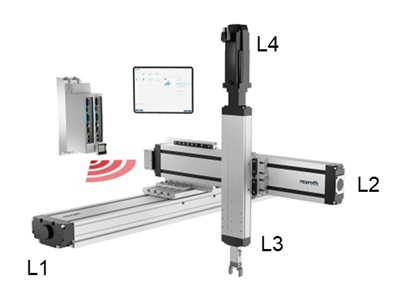

%Limpieza de pantalla
clear all
close all
clc
%SECCIÓN 1
%Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) th4(t) t L1(t) L2(t) L3(t) L4(t)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 2
%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[1 1 1 1];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 3
%Creamos el vector de coordenadas articulares
Q= [th1, th2, th3, th4];
disp('Coordenadas generalizadas');

Coordenadas generalizadas


pretty (Q);

(th1(t), th2(t), th3(t), th4(t))



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 4
%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
disp('Velocidades generalizadas');

Velocidades generalizadas


pretty (Qp);

/  d          d          d          d        \
| -- th1(t), -- th2(t), -- th3(t), -- th4(t) |
\ dt         dt         dt         dt        /



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 5
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 6
%Junta 1 
%Posición de la junta 1 respecto a 0
P(:,:,1)= [0; 0; L1];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,1)= [ 0  0  1;
            0  1  0;
           -1  0  0];


%Junta 2
%Posición de la junta 2 respecto a 1
P(:,:,2)= [0; 0; L2];
%Matriz de rotación de la junta 2 respecto a 1
R(:,:,2)= [1  0   0;
           0  0  -1;
           0  1   0];

%Junta 3
%Posición de la junta 3 respecto a 2
P(:,:,3)= [0; 0; L3];
%Matriz de rotación de la junta 3 respecto a 2
R(:,:,3)= [1  0  0;
           0  1  0;
           0  0  1];

%Junta 4
%Posición de la junta 4 respecto a 3
P(:,:,4)= [0; 0; L4];
%Matriz de rotación de la junta 4 respecto a 3
R(:,:,4)= [1  0  0;
           0  1  0;
           0  0  1];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 7
%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 
%Inicializamos las INVERSAS de las matrices de rotación vistas desde el marco de referencia inercial
RO_inv(:,:,GDL)= R(:,:,GDL); 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 8
for i = 1:GDL
    i_str= num2str(i);
    %Locales
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    RO_inv(:,:,i)= transpose(RO(:,:,i));
    PO(:,:,i)= T(1:3,4,i);
   %pretty(RO(:,:,i));
   % pretty(RO_inv(:,:,i));
   % pretty(PO(:,:,i));
end

Matriz de Transformación local A1


/  0, 0, 1,   0   \
|                 |
|  0, 1, 0,   0   |
|                 |
| -1, 0, 0, L1(t) |
|                 |
\  0, 0, 0,   1   /



Matriz de Transformación global T1


/  0, 0, 1,   0   \
|                 |
|  0, 1, 0,   0   |
|                 |
| -1, 0, 0, L1(t) |
|                 |
\  0, 0, 0,   1   /



Matriz de Transformación local A2


/ 1, 0,  0,   0   \
|                 |
| 0, 0, -1,   0   |
|                 |
| 0, 1,  0, L2(t) |
|                 |
\ 0, 0,  0,   1   /



Matriz de Transformación global T2


/  0, 1,  0, L2(t) \
|                  |
|  0, 0, -1,   0   |
|                  |
| -1, 0,  0, L1(t) |
|                  |
\  0, 0,  0,   1   /



Matriz de Transformación local A3


/ 1, 0, 0,   0   \
|                |
| 0, 1, 0,   0   |
|                |
| 0, 0, 1, L3(t) |
|                |
\ 0, 0, 0,   1   /



Matriz de Transformación global T3


/  0, 1,  0,  L2(t) \
|                   |
|  0, 0, -1, -L3(t) |
|                   |
| -1, 0,  0,  L1(t) |
|                   |
\  0, 0,  0,    1   /



Matriz de Transformación local A4


/ 1, 0, 0,   0   \
|                |
| 0, 1, 0,   0   |
|                |
| 0, 0, 1, L4(t) |
|                |
\ 0, 0, 0,   1   /



Matriz de Transformación global T4


/  0, 1,  0,      L2(t)      \
|                            |
|  0, 0, -1, - L3(t) - L4(t) |
|                            |
| -1, 0,  0,      L1(t)      |
|                            |
\  0, 0,  0,        1        /



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Calculamos la matriz de transformación del marco de referencia inercial
%visto desde el actuador final
% disp(strcat('Matriz de Transformación T', GDL_str,'_O calculada de forma manual'));
% RF_O=RO_inv(:,:,GDL);
% PF_O=-RF_O*PO(:,:,GDL);
% TF_O= simplify([RF_O PF_O; Vector_Zeros 1]);
% pretty(TF_O);   

%disp(strcat('Matriz de Transformación T', GDL_str,'_O calculada de forma auntomática'));
%pretty(simplify(inv(T(:,:,GDL))));

%SECCIÓN 9
%Calculamos el jacobiano lineal de forma diferencial
disp('Jacobiano lineal obtenido de forma diferencial');

Jacobiano lineal obtenido de forma diferencial


%Derivadas parciales de x respecto a L1, L2, L3 y L4
Jv11= functionalDerivative(PO(1,1,GDL), L1);
Jv12= functionalDerivative(PO(1,1,GDL), L2);
Jv13= functionalDerivative(PO(1,1,GDL), L3);
Jv14= functionalDerivative(PO(1,1,GDL), L4);
%Derivadas parciales de y respecto a L1, L2, L3 y L4
Jv21= functionalDerivative(PO(2,1,GDL), L1);
Jv22= functionalDerivative(PO(2,1,GDL), L2);
Jv23= functionalDerivative(PO(2,1,GDL), L3);
Jv24= functionalDerivative(PO(2,1,GDL), L4);
%Derivadas parciales de z respecto a L1, L2, L3 y L4
Jv31= functionalDerivative(PO(3,1,GDL), L1);
Jv32= functionalDerivative(PO(3,1,GDL), L2);
Jv33= functionalDerivative(PO(3,1,GDL), L3);
Jv34= functionalDerivative(PO(3,1,GDL), L4);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13 Jv14;
               Jv21 Jv22 Jv23 Jv24;
               Jv31 Jv32 Jv33 Jv34]);
pretty(jv_d);

/ 0, 1,  0,  0 \
|              |
| 0, 0, -1, -1 |
|              |
\ 1, 0,  0,  0 /



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%SECCIÓN 10
%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 %Casos: articulación rotacional
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
        end
        
        %Para las juntas prismáticas
     elseif RP(k)==1 %Casos: articulación prismática
%         
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ 0, 1,  0,  0 \
|              |
| 0, 0, -1, -1 |
|              |
\ 1, 0,  0,  0 /



disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 0, 0, 0 \
|            |
| 0, 0, 0, 0 |
|            |
\ 0, 0, 0, 0 /





disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/        _________        \
|         d               |
|        -- th2(t)        |
|        dt               |
|                         |
|   _________   _________ |
|    d           d        |
| - -- th3(t) - -- th4(t) |
|   dt          dt        |
|                         |
|        _________        |
|         d               |
|        -- th1(t)        |
\        dt               /



disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/ 0 \
|   |
| 0 |
|   |
\ 0 /




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%